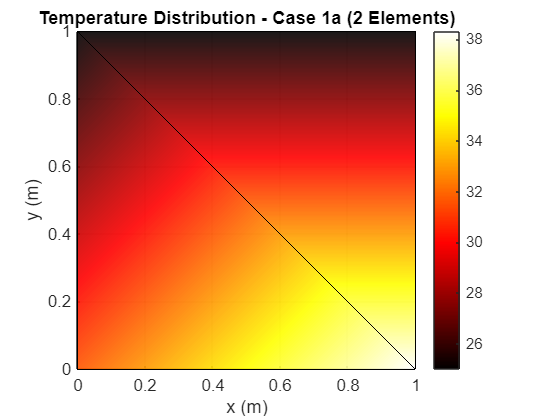

clc; clear;

T0 = 25;                % Dirichlet temperature on 4th side
k = 50;                 % Thermal conductivity
q_mag = 1000;           % Point source magnitude (W/m²)

% Define the four corner nodes of the square
nodes = [0, 0;          % Node 1: bottom-left
         1, 0;          % Node 2: bottom-right
         0, 1;          % Node 3: top-left
         1, 1];         % Node 4: top-right

% Center coordinates
xc = 0.5;
yc = 0.5;

% Define the two triangular elements
elements = [1, 2, 3;    % Element 1: using nodes 1, 2, 3
            2, 4, 3];   % Element 2: using nodes 2, 4, 3

%% FEM Assembly
N = size(nodes, 1);     % Number of nodes (4)
K = zeros(N);           % Global stiffness matrix
F = zeros(N, 1);        % Global force vector

% Loop through each element
for e = 1:size(elements, 1)
    
    node_ids = elements(e,:);
    coords = nodes(node_ids,:);

    Q = [1, 0, -1; 0, 1, -1];
    %J = Q * coords;
    x = coords(:, 1); y = coords(:, 2);
    J=[x(1)-x(3),x(2)-x(3);y(1)-y(3),y(2)-y(3)];
    Ae = 0.5 * abs(det(J));
    ke = k * Ae * Q' * inv(J) * inv(J') * Q;
    
    % Assemble into global stiffness matrix
    K(node_ids, node_ids) = K(node_ids, node_ids) + ke;
    
    % Calculate barycentric coordinates of the center point for this element
    % Shape functions for triangular elements
    x_el = coords(:,1);
    y_el = coords(:,2);
    
    % Calculate the area of the element
    A_e = 0.5 * abs((x_el(2)-x_el(1))*(y_el(3)-y_el(1)) - (x_el(3)-x_el(1))*(y_el(2)-y_el(1)));
    
    % Check if center point lies within this element using barycentric coordinates
    A1 = 0.5 * abs((x_el(2)-xc)*(y_el(3)-yc) - (x_el(3)-xc)*(y_el(2)-yc));
    A2 = 0.5 * abs((xc-x_el(1))*(y_el(3)-y_el(1)) - (x_el(3)-x_el(1))*(yc-y_el(1)));
    A3 = 0.5 * abs((x_el(2)-x_el(1))*(yc-y_el(1)) - (xc-x_el(1))*(y_el(2)-y_el(1)));
    
    % Sum of sub-areas should approximately equal the total area if point is inside
    if abs((A1 + A2 + A3) - A_e) < 1e-10
       
       N1 = A1/A_e;
       N2 = A2/A_e;
       N3 = A3/A_e;

        % Apply heat source at the element containing the center
        Fe = q_mag/2 * [N1; N2; N3]; 
        F(node_ids) = F(node_ids) + Fe;
    end
end

%% Apply Boundary Conditions
K_mod = K;
F_mod = F;

% Top edge nodes (4th side) - Dirichlet boundary condition
top_nodes = find(abs(nodes(:,2) - 1) == 0 );
for n = top_nodes'
    K_mod(n,:) = 0;
    K_mod(n,n) = 1;
    F_mod(n) = T0;
end

% Other boundaries are naturally insulated (no additional constraints needed)

%% Solve System
T = K_mod \ F_mod;

%% Plot Results
figure;
% Use trisurf with interpolated shading for better visualization
trisurf(elements, nodes(:,1), nodes(:,2), T, ...
    'EdgeColor', 'k', 'FaceColor', 'interp', 'FaceAlpha', 0.9);
view(2); axis equal tight; colorbar;
xlabel('x (m)'); ylabel('y (m)'); 
title('Temperature Distribution - Case 1a (2 Elements)');
colormap('hot');

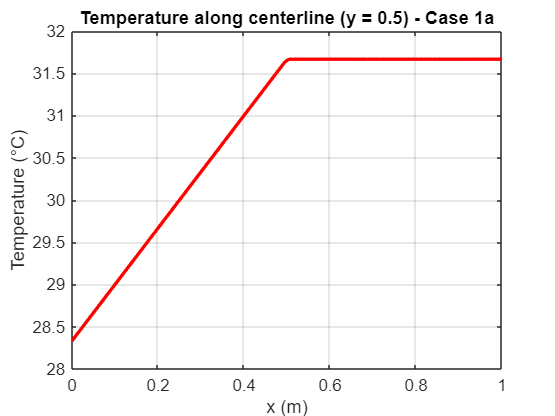


% Create a finer grid for smoother centerline plot
x_vals = linspace(0, 1, 100);
y_vals = 0.5 * ones(size(x_vals));
T_mid = griddata(nodes(:,1), nodes(:,2), T, x_vals, y_vals, 'linear');

% Plot centerline profile
figure;
plot(x_vals, T_mid, 'r-', 'LineWidth', 2);
xlabel('x (m)'); ylabel('Temperature (°C)');
title('Temperature along centerline (y = 0.5) - Case 1a');
grid on;